# Concrete Crack Classification using Bag-of-Features and Support Vector Machine (SVM)

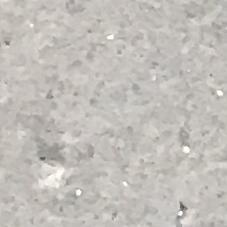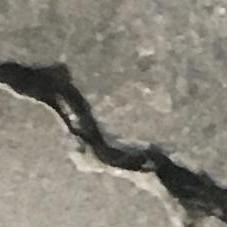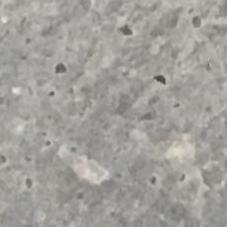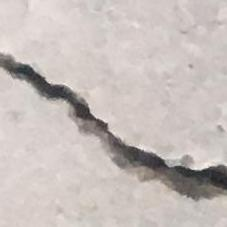

Introduction:

In this project, we developed a classification system for detecting cracks in concrete images. The goal was to accurately categorize images as either containing cracks or being crack-free.

Methodology:

- Data Collection: We collected a dataset comprising 2000 images of concrete surfaces, with labels indicating the presence or absence of cracks.

- Feature Extraction: We employed a bag-of-features approach to extract relevant features from the images. This technique captures the distribution of visual patterns within each image, providing a compact representation suitable for classification.

- Model Training: We trained a Support Vector Machine (SVM) classifier using the extracted features. SVM is a powerful supervised learning algorithm that effectively separates classes by finding the optimal hyperplane in the feature space.

- Evaluation: The performance of the model was evaluated using standard evaluation metrics such as accuracy, precision, recall, and F1-score. The trained model achieved an impressive accuracy of 99% on both the training and testing datasets, indicating its robustness and generalization capability.

Results:

Our classification system demonstrated outstanding performance, achieving a remarkable accuracy of 99% on both the training and testing datasets. This high level of accuracy suggests that the model is highly effective at distinguishing between concrete images with and without cracks. The robustness of the model makes it suitable for real-world applications such as automated inspection and monitoring of concrete structures.

## Preparing the Data

filePath = uigetdir;
dsConcrete = imageDatastore(filePath,"IncludeSubFolders",true,...
    "LabelSource","foldernames");
dsConcrete.Labels = renamecats(dsConcrete.Labels,["No Crack" "Crack"]);
[dsTrain,dsTest] = splitEachLabel(dsConcrete,0.8,"randomize");

 display some images 

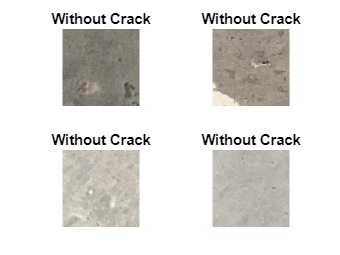

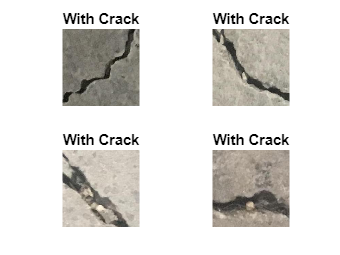

displayCrackImages()

## Generating Predictor Features with BagOfFeatures

Bag of Features is a technique commonly used in computer vision for image classification tasks. It involves extracting local features from images, clustering them into visual words, and then representing each image as a histogram of visual word occurrences. This process captures the spatial distribution of visual patterns in the images, which can be used as features for classification. The function utilizes the BagOfFeatures function in MATLAB's Computer Vision Toolbox to extract features from the input dataset and returns predictor tables for both training and testing datasets.

[predTableTrain, predTableTest] = extractFeaturesAndLabels(dsTrain, dsTest);

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Encoding 1600 images...done.

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: No Crack
* Image category 2: Crack
* Encoding 400 images...done.


## Train the Model

After exploring various models using the classification app in MATLAB, the medium Gaussian SVM stood out as the preferred choice for training the model. This decision was based on its ability to achieve higher accuracy and produce better results compared to other models tested.

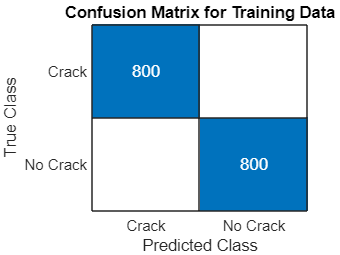

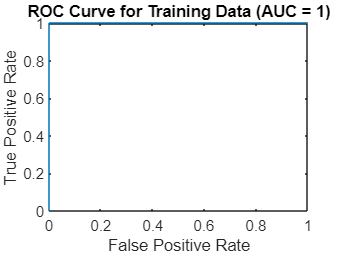

[trainedClassifier, validationAccuracy,predictedLabelsTrain] = TrainClassifierAndEvaluate(predTableTrain);

#### Visualize False Predictions of Training Data

VisualizeFalsePredictions(dsTrain, predTableTrain, predictedLabelsTrain);

##  Test the model

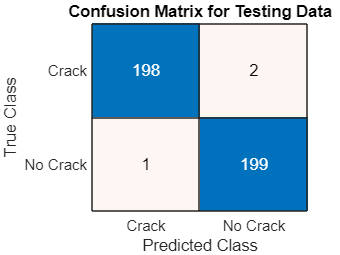

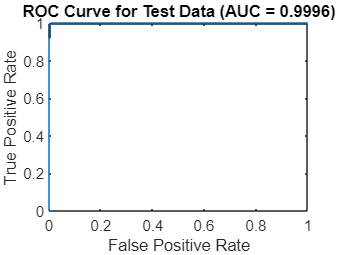

predictedLabelsTest =EvaluateTestData(trainedClassifier, predTableTest); 

#### Visualize False Predictions of testing Data

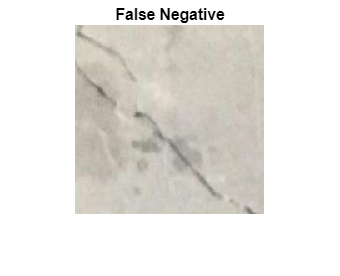

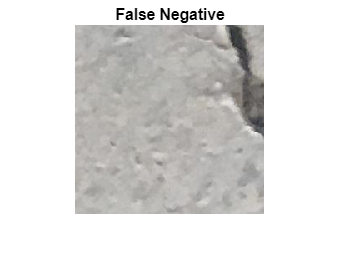

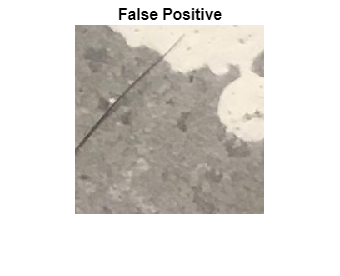

VisualizeFalsePredictions(dsTest, predTableTest, predictedLabelsTest);

##  Conclusion:

In conclusion, we have successfully developed a classification system for concrete crack detection using a combination of bag-of-features and Support Vector Machine (SVM). The model's exceptional accuracy and robustness make it a valuable tool for identifying cracks in concrete surfaces, offering potential benefits in terms of safety, maintenance, and structural integrity. Additionally, the results demonstrate a higher accuracy without resorting to CNN or deep learning approaches, which often consume substantial resources and time. Understanding the specific project requirements is crucial for selecting between traditional machine learning and deep learning approaches, ensuring optimal outcomes.

matlab.internal.liveeditor.openAndConvert('CrackClassification.mlx', 'Crack Classification.pdf', 'HideCode',false);